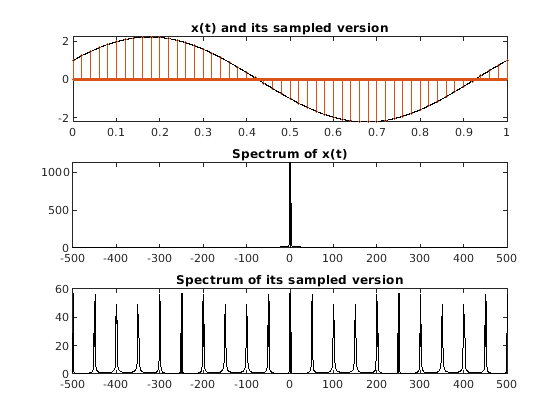

clc;
close all;

t = 0:0.001:1;
x = cos(2*pi*t) + 2*sin(2*pi*t);

Ts = 0.02;
n = [0:Ts:1];
Nfacor = round(Ts/0.001);
BW = 10;

%Generating the impulse trainf or the ideal filter

p = ones(1,length(x));
p = downsample(p, Nfacor);
p = upsample(p, Nfacor);
p = p(1:length(x));

xs = x.*p;

%Plotting x(t) and it's sampled version

subplot(3, 1, 1)
plot(t, x, 'k');
hold on
stem(t, xs, 'Markersize', 1);
title('x(t) and its sampled version');

%Finding the spectrum of x(t) and it's sampled version

Nfft = 2^ceil(log2(length(x)));
Fmax = 1/(2*0.001);
Faxis = linspace(-Fmax, Fmax, Nfft);
X = fftshift(fft(x, Nfft));
Xs = fftshift(fft(xs, Nfft));

subplot(3, 1, 2)
plot(Faxis, abs(X), 'k');
title('Spectrum of x(t)');

subplot(3, 1, 3)
plot(Faxis, abs(Xs), 'k');
title('Spectrum of its sampled version');

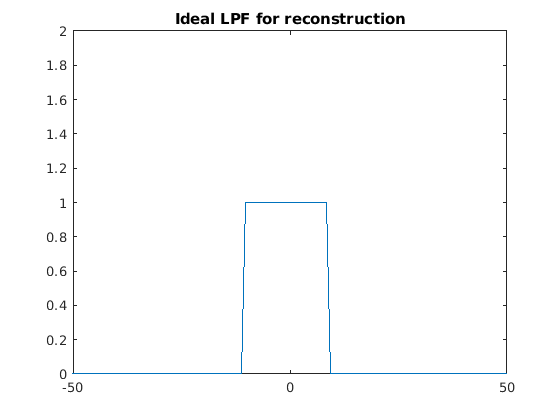



Hlpf = zeros(1, Nfft);
Hlpf(Nfft/2-BW:Nfft/2+BW-1) = 1;
figure;
plot(Faxis, Hlpf);
axis([-50, 50, 0, 2]);
title('Ideal LPF for reconstruction');

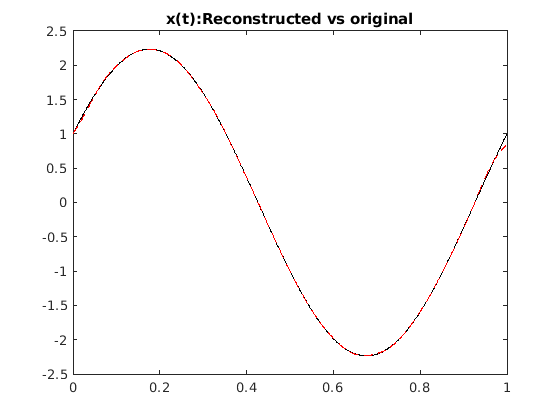


Xr = Nfacor * Hlpf.*Xs;

xr = real(ifft(fftshift(Xr)));
xr = xr(1:length(x));


figure;
plot(t, x, '-k');
hold on
plot(t, xr, '--r')
title('x(t):Reconstructed vs original');